# Estudo de análise de Estabilidade de Tensão

clc;
close all;
format long;
cd(fileparts(matlab.desktop.editor.getActiveFilename)) % Mudo o folder do Matlab para o mesmo do arquivo mlx (é necessário, pois ele não muda sozinho para .mlx)

## Sistema Utilizado nas análises

FILENAME = 'Sistema_HVDC_FOZ_IBIUNA';
FILENAME = strcat('Sistemas\',FILENAME);

## Variáveis necessárias para cada função

Dados para Resolver o Fluxo de Potência:

PlotaGraficoPQHVDC = true;
AlfaEsp  = 13.6;  % Ang de Disparo do Retificador esperado (em graus)
GammaEsp = 17;  % Ang de extinsão do Inversor esperado (em graus)
Tapr     = 0.96;  % Tap Ret Esp
Tapi     = 0.95;  % Tap Inv Esp
Ielo     = 1;  % Corrente Esp em PU
VdRef    = 1;  % Tensão Esp em Pu
MododoElo = 0; % Seleciona o Tipo de Controle

Dados para o Plot das Curvas P e Q Constantes

iIte = 100;         % Número de pontos gerados
VespMin = 0.75;     % Tensão inicial do Plot (Caso o ponto inicial não seja possível o gráfico não será gerado)
VespMax = 1.2;      % Tensão final do Plot (Ou até divergir)
Q1 = 0.55;          % Valor da Potência Reativa Constante na curva P1
Q2 = 0.5            % Valor da Potência Reativa Constante na curva P2

Q2 =    0.500000000000000


P1 = 0.9;           % Valor da Potência Ativa Constante na curva P1
P2 = 1.0;           % Valor da Potência Ativa Constante na curva P2

## Análise das Variáveis HVDC

[~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~ ...
    , DHVDC, ~, XhvdcEsp]=Dados(FILENAME);

DHVDC(1,15) = GammaEsp*2*pi/360;        % Ang de Disparo do Inv Esp
DHVDC(1,12) = AlfaEsp*2*pi/360;         % Ang de Disparo do Ret Esp
DHVDC(1,33) = 1/Tapr;                   % Tap Ret Esp
DHVDC(1,34) = 1/Tapi;                   % Tap Inv Esp
DHVDC(1,18) = Ielo;                     % Iesp
DHVDC(1,22) = VdRef;                    % VdrefEsp
DHVDC(1,21) = MododoElo;                % SE 0 = normal, se 1 = High Mvar Consumption, se 2 = Controle do artigo, Se 3 = Convencional
[Flag, Xhvdc, ModoHVDC] = Fluxo_de_Potencia_Convencional(1, DHVDC, XhvdcEsp);

xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx

				    FLUXO DE POTÊNCIA 
 
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                                Variáveis de Estado das Linhas HVDC                                 
----------------------------------------------------------------------------------------------------
    DE    PARA      VRet      VInv    Ir    Ii        Pr         Pi             Qr                  Qi       
    __    ____    ________    ____    __    __    __________    _____    ________________    ________________

    1      2     

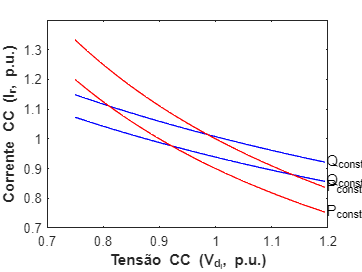


if PlotaGraficoPQHVDC == true
    
    Range = VespMax-VespMin;
    DeltaVdc = Range/(iIte-1);
    IdcConst1 = zeros(iIte,1);
    VdcConst1 = zeros(iIte,1);
    DHVDC(1,27) = 2; % Controle Pot Reativa Const
    DHVDC(1,18) = Q1; % Valor em Pu da Potencia reativa Const
    DHVDC(1,22) = VespMin;
    Imprime = 0;
    for i = 1:iIte
        [Flag, Xhvdc, ModoHVDC] = Fluxo_de_Potencia_Convencional(Imprime, DHVDC, XhvdcEsp);
        DHVDC(1,22) = DHVDC(1,22) + DeltaVdc;
        iItebreak = i;
        if (sum(ModoHVDC ~= 0) ~= 0 || Flag~=1)
            iItebreak = i
            [Flag, Xhvdc, ModoHVDC] = Fluxo_de_Potencia_Convencional(1, DHVDC, XhvdcEsp);
            break;
        end
        VdcConst1(i) = Xhvdc(2);
        IdcConst1(i) = Xhvdc(5);
    end
    VdcConst1 = VdcConst1(1:iItebreak-1);
    IdcConst1 = IdcConst1(1:iItebreak-1);
    plot(VdcConst1,IdcConst1,'b')



    IdcConst2 = zeros(iIte,1);
    VdcConst2 = zeros(iIte,1);
    DHVDC(1,27) = 2; % Controle Pot Reativa Const
    
    DHVDC(1,18) = Q2; % Valor em Pu da Potencia reativa Const
    DHVDC(1,22) = VespMin;
    Imprime = 0;
    for i = 1:iIte
        [Flag, Xhvdc, ModoHVDC] = Fluxo_de_Potencia_Convencional(Imprime, DHVDC, XhvdcEsp);
        DHVDC(1,22) = DHVDC(1,22) + DeltaVdc;
        if (sum(ModoHVDC ~= 0) ~= 0 || Flag~=1)
            iItebreak = i
            [Flag, Xhvdc, ModoHVDC] = Fluxo_de_Potencia_Convencional(1, DHVDC, XhvdcEsp);
            break;
        end
        VdcConst2(i) = Xhvdc(2);
        IdcConst2(i) = Xhvdc(5);
    end
    VdcConst2 = VdcConst2(1:iItebreak-1);
    IdcConst2 = IdcConst2(1:iItebreak-1);
    hold on;
    plot(VdcConst2,IdcConst2,'b');
    
    VdcConstP1 = VdcConst2;
    
    IdcConstP1 = P1./VdcConstP1;
    VdcConstP2 = VdcConst2;
    
    IdcConstP2 = P2./VdcConstP2;
    hold on;
    plot(VdcConstP1,IdcConstP1,'r');
    hold on;
    plot(VdcConstP2,IdcConstP2,'r');
    text(VdcConst2(end),IdcConst1(end),strcat("Q_{const} (",num2str(Q1)," pu)"),'FontSize',11);
    text(VdcConst2(end),IdcConst2(end),strcat("Q_{const} (",num2str(Q2)," pu)"),'FontSize',11);
    text(VdcConstP1(end),IdcConstP1(end),strcat("P_{const} (",num2str(P1)," pu)"),'FontSize',11);
    text(VdcConstP2(end),IdcConstP2(end),strcat("P_{const} (",num2str(P2)," pu)"),'FontSize',11);
    xlabel("Tensão CC (V_{d_i}, p.u.)",'FontSize',11,'FontWeight','bold')
    ylabel("Corrente CC (I_{r}, p.u.)",'FontSize',11,'FontWeight','bold')
end